# Exploring Eigenvalues & Eigenvectors

## Introduction

In this activity we will learn how to calculate the eigenvalues of an $n\times n$ matrix A using the characteristic equation. We will also learn how to use the MATLAB function [`eig()`](https://au.mathworks.com/help/matlab/ref/eig.html) to calculate eigenvalues and eigenvectors. Finally, we will explore a geometric interpretation of matrices as transformations to see its effect on a set of points and also how the eigenvalues and eigenvectors are related to each other.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

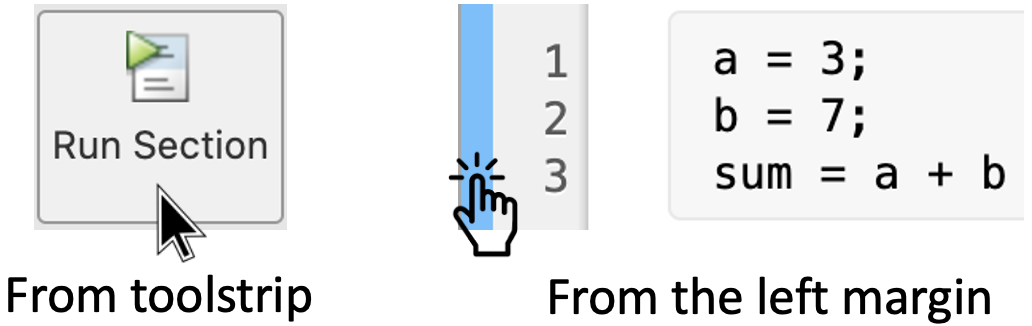

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Eigenvalues & Eigenvectors

#### 1.1 Definition

An *eigenvector* of an $n\times n$ matrix $A$ is a **nonzero** column vector such that

$A\underline{x}=\lambda\underline{x}$,

for some number $\lambda$ (possible complex), called the *eigenvalue* corresponding to $\underline{x}$. What the previous expression is saying is that the matrix-vector product $A\underline{x}$ gives the same result as just scaling the eigenvector $\underline{x}$ by some value $\lambda$.

The eigenvalues of $A$ are the roots of the *characteristic polynomial *


$$p(t) = |A-t\cdot  I|$$


where $I$ is the $n\times n$ identity matrix.

The characteristic polynomial of the matrix


$$A_1 =  \left[
\begin{array}{r}
1 & 3 \\
4 & 2
\end{array}
\right]$$


can be computed using the following MATLAB commands:

A_1 = [1 3; 4 2];
% The next line creates a symbolic variable 't'
syms t
% MATLAB can now manipulate expressions using 't'
p = det(A_1 - t * eye(2))


The roots of $p(t)$ can be calculated with the MATLAB command [`solve(p)`](https://au.mathworks.com/help/symbolic/solve.html). These are the eigenvalues of $A_1$. Try it for yourself! Add this command in the previous code.

#### 1.2 The `eig()` function

MATLAB has a built-in function called [`eig()`](https://au.mathworks.com/help/matlab/ref/eig.html) to calculate the eigenvalues of a matrix and give corresponding eigenvectors. For example, to calculate the eigenvalues of the matrix $A_1$, we write the following code:

eig(A_1)

which means that the two eigenvalues of A are `-2` and `5`. Compare this result with the solution of the characteristic polynomial from the previous section.

To find the eigenvectors you need to supply a vector of two variables to record the two outputs of the function `eig` (here we've called them `V` and `D`, but you can give them more meaningful variable names):

[V, D] = eig(A_1)

The columns of the first output, `V`, gives the eigenvectors of the matrix `A_1`, the diagonal elements of `D` give the eigenvalues corresponding to the eigenvectors in `V`, respectively. Thus, we have that the matrix $A_1$ has the eigenvalues $\lambda_1=-2$ and $\lambda_2=5$ with respective eigenvectors

$\underline{v_1} = \left[ 
\begin{array}{r}
-0.7071 \\
0.7071
\end{array}
\right]$ and $\underline{v_2} = \left[ 
\begin{array}{r}
-0.6 \\
-0.8
\end{array}
\right]$.

#### **Fun fact!**

`V` and `D` are matrices that are sometimes known as the "eigenvalue decomposition of `A`", and it can be shown that

$AV = VD$ or $A = VDV^{-1}$.

You can check this fact in MATLAB with the following code:

V * D * V^(-1)

Is the output really equal to the matrix $A_1$ defined above?

### 2. Geometric interpretation of eigenvalues & eigenvectors

When the eigenvectors are 2-dimensional they can be plotted as **arrows** using the command

[`quiver(x,y,u,v)`](https://au.mathworks.com/help/matlab/ref/quiver.html)

(sometimes we like to plot vectors with **arrows** to show the direction). This command plots an arrow starting at the point `(x,y)` and ending at the point `(u,v)` on the figure. The arrowhead will be at the point `(u,v)`. We can easily plot the same vector using the `plot` function; however it won't have an arrowhead.

For example, let's plot the eigenvectors of the matrix `A_1`. To do this we write:

clf; % clears the figure of previous plots, if there is any
hold on;
quiver(0, 0, V(1,1), V(2,1),...      % 1st eigenvector
    'Color','b', 'LineWidth', 1.5);  % This adds format
quiver(0, 0, V(1,2), V(2,2),...      % 2nd eigenvector
    'Color','g', 'LineWidth', 1.5);  % This adds format
hold off;
grid on, axis([-1 1 -1 1]);

The first eigenvector is shown in blue, and the second eigenvector is shown in green.

#### 2.1 Transformations

Multiplying a vector $\underline{v}$ by a matrix on its left results in a new vector,

$A\underline{v}=\underline{w}$.

Therefore a matrix can be thought of as a *transformation* that takes a vector as an input and outputs a *transformed* vector.

For example, let's  investigate the effect of the matrix 


$$T = \left[
\begin{array}{r}
3 & 1 \\
1 & 2
\end{array}
\right]$$


has on its eigenvectors under multiplication.

Run the following code to analyse the plot:

T = [3 1; 1 2];  % Define matrix T.
[evecs,evals] = eig(T)   % Compute eigenstuff. Don't worry about the warning message.
v1 = evecs(:,1);         % First eigenvector, using matrix indexing
v2 = evecs(:,2);         % Second eigenvector, using matrix indexing
u1 = T * v1;             % Apply matrix T to each eigenvector,
u2 = T * v2;             % we can also use the command 'mtimes()'.
clf;                     % clears the figure of previous plots, if there is any
hold on;
% Plot eigenvectors %
quiver(0, 0, v1(1), v1(2), 'Color', 'b', 'LineWidth', 3);
quiver(0, 0, v2(1), v2(2), 'Color', 'r', 'LineWidth', 3);
% Plot eigenvectors transform by T %
quiver(0, 0, u1(1), u1(2), 'Color', 'm', 'LineWidth', 1.5);
quiver(0, 0, u2(1), u2(2), 'Color', 'k', 'LineWidth', 1.5);
hold off;
grid on, axis equal

**Note:** Here we use matrix **indexing** to get each eigenvector. More information here: [Matrix indexing](https://au.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html).

The first eigenvector `v1` is plotted in blue before being transformed by `T`, and then in magenta after its transformation, this is `u1`. The second vector v2 is plotted in red and then its transformation `u2` in black. What do you notice about the two sets of vectors? What do you think it happens when you apply the transformation  on **other** vectors (non-eigenvectors) e.g. $\underline{x}= \left[
\begin{array}{r}
1 \\
0
\end{array}
\right]$ and $\underline{y}= \left[
\begin{array}{r}
0 \\
1
\end{array}
\right]$?

## 3. Hands on practice

Let's practice what we just learned.

### Activity 1:

Use the `eig()` command to find the eigenvalues and eigenvectors of the matrix

$A =  \left[
\begin{array}{r}
2.3 & 1.2 \\
-1.2 & -0.2
\end{array}
\right]$.

Use matrix **indexing** to give the *eigenvalues *of $T$ explicitly. Use different variable names to identify them. 

Write you code here:

Use matrix **indexing** to the two *eigenvectors* of $T$ explicitly. Use different variable names to identify them. 

Write your code here:

### Activity 2:

We can transform a set of points $(x,y)$ by a matrix $T$ by the following equation


$$T\left[
\begin{array}{r}
x \\
y
\end{array}
\right] = 
\left[
\begin{array}{r}
u \\
v
\end{array}
\right]$$


where $T$ is a 2×2 matrix and $(x,y)\in \mathbb R^2$. To visualise this transformation of points we will use the function `matrixTransform` defined in the **Appendix** (You **do not** need to modify, nor understand it).

Let's see how the matrix


$$T = \left[
\begin{array}{r}
3 & 1 \\
1 & 2
\end{array}
\right]$$


transforms a set of points with the following code:

T = [3 1;1 2];
matrixTransform(T)

Run this section to see the animation. It might take a few seconds. When the animation is done, you can drag the slider to apply the transformation manually.

Use the function `matrixTransform` to analyse the effect of the following matrices:

- $T1 = \left[
\begin{array}{r}
2.3 & 1.2 \\
-1.2 & -0.2
\end{array}
\right]$, 

-  $T2 = \left[
\begin{array}{r}
\cos\theta & -\sin\theta  \\
\sin\theta & \cos \theta
\end{array}
\right]$ with $\theta=\frac{\pi}{4}$,

- $T3 = \left[
\begin{array}{r}
1 & 2 \\
1 & 2
\end{array}
\right]$.

**Part 1 -** Write your code here:

**Part 2 -** Write you code here:

**Part 3 -** Write you code here:

Once you wrote your code, run it to analyse the behaviour of each transformation. What do you notice? What do you wonder? What can you say about the eigenvectors for each case? If necessary, calculate the eigenvalues and eigenvectors?

## Appendix: Pre-defined functions

function [] = matrixTransform(T)

% 'matrixTransform' is a function which will visualise 
% the effect of your 2-by-2 transformation matrix T on 
% a set of grid points. It will also plot the eigenvectors 
% of the matrix T if there are two real eigenvectors. 

close all;

minX = -10;
maxX = 10;
minY = -10;
maxY = 10;
n = 10;
pad = 5;

corners = [minX, maxX, minX, maxX; maxY, maxY, minY, minY];
corners = [corners, T*corners];
corners = [min(corners(:)) max(corners(:)) min(corners(:)) max(corners(:))] + pad*[-1,1,-1,1];

A = T-eye(2);

[ evec, evals ] = eig(T); % Dont' worry about the warning message :)

axis(corners);
axis equal;
xLim = get(gca, 'XLim');
yLim = get(gca, 'YLim');

hold on;
if trace(T)^2-4*det(T) > 0
    nick = 1;
elseif trace(T)^2-4*det(T) == 0
    if isreal(eig(R))
        nick = 1;
    else
        nick = 0;
    end
else
    nick = 0;
end

newXY = zeros(2);

for t = linspace(0,1,100)
    cla;
    if nick
        sevec = (A*t+eye(2))*evec;
        quiver(0, 0, sevec(1,1)*10, sevec(2,1)*10, 'LineWidth', 2);
        quiver(0, 0, sevec(1,2)*10, sevec(2,2)*10, 'LineWidth', 2);
    end
    for x = linspace(minX, maxX, n)
        index = 1;
        for y = linspace(minY, maxY, n)
            if nick
                newXY(:,index) = (A*t+eye(2))*[x;y];
            else
                [t1,r1] = cart2pol(x,y);
                [t2,r2] = cart2pol(T(1)*x+T(2)*y,T(3)*x+T(4)*y);
                if t2 >= t1
                    t2 = t2-2*pi;
                end
                [xp, yp] = pol2cart(t1+(t2-t1)*t, r1+(r2-r1)*t);
                newXY(:, index) = [xp;yp];
            end
            index = index+1;
        end
        plot(newXY(1,:), newXY(2,:), '.', ...
            'MarkerEdgeColor',[0.4 (maxX-x)/(maxX-minX) 0.8]);
        plot(newXY(1,1), newXY(2,1), '.m');
        plot([0, 0],yLim,'-k');
        plot(xLim,[0,0],'-k');
    end
    grid on
    
    if t == 0
        pause(1);
    else
        pause(0.005);
    end
end

end